# **Introduction To Robotics Homework # 5**

## **Huzaifah Tariq Ahmed (ha07151) & Syed Asghar Abbas Zaidi (sz07201)**

## **Problem # 1**

**First Segment**

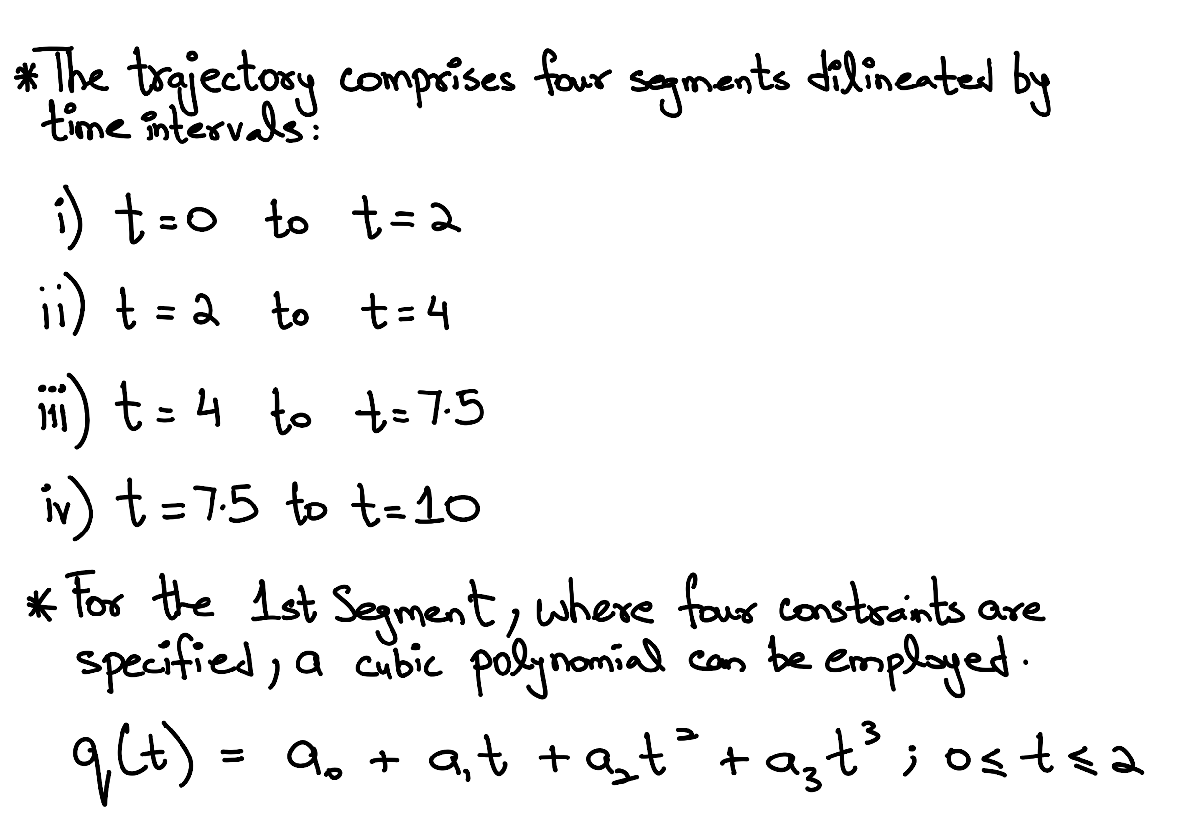

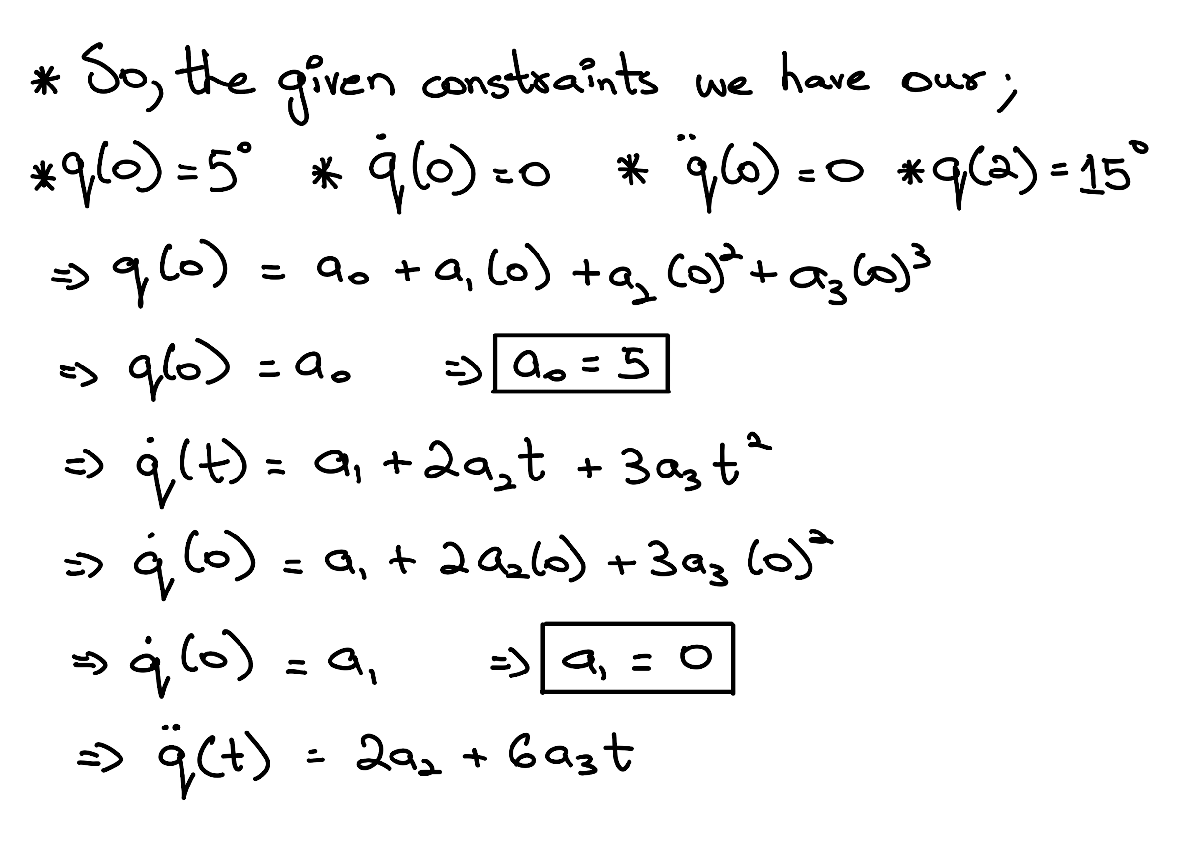

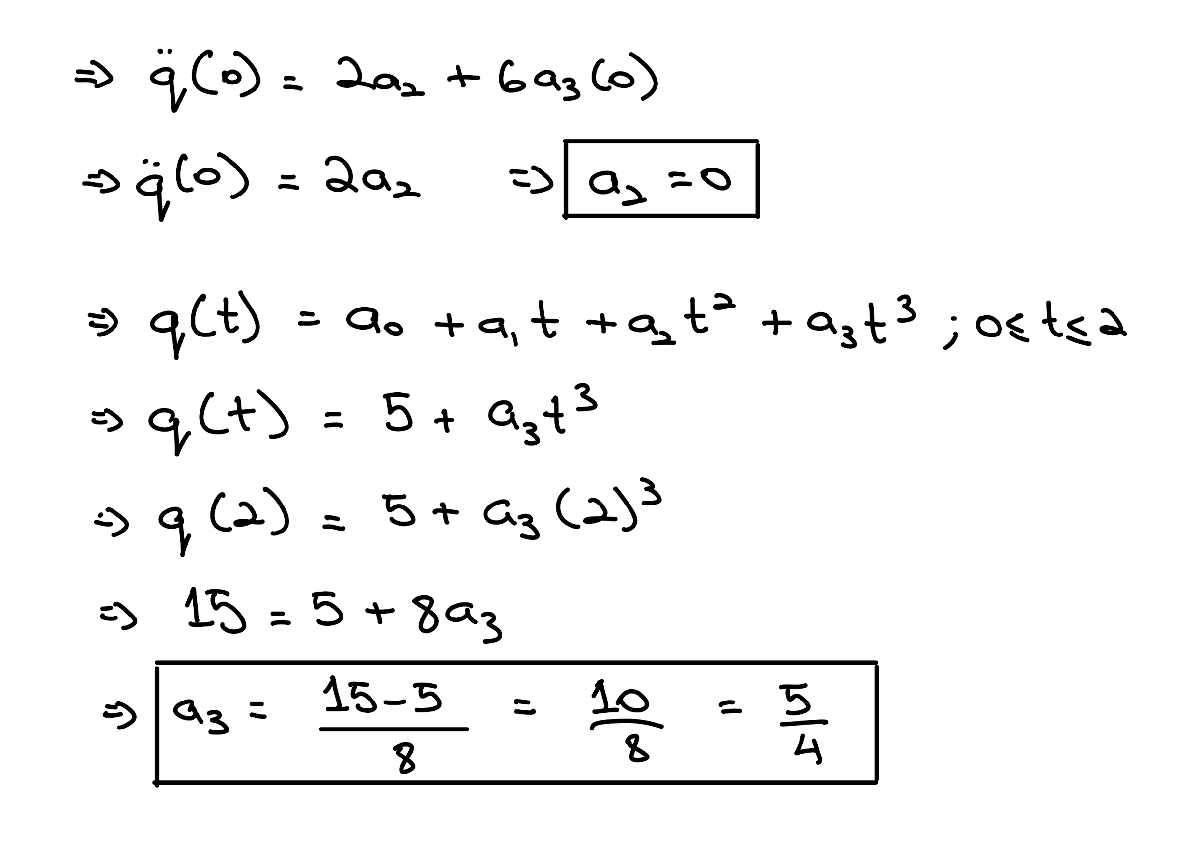

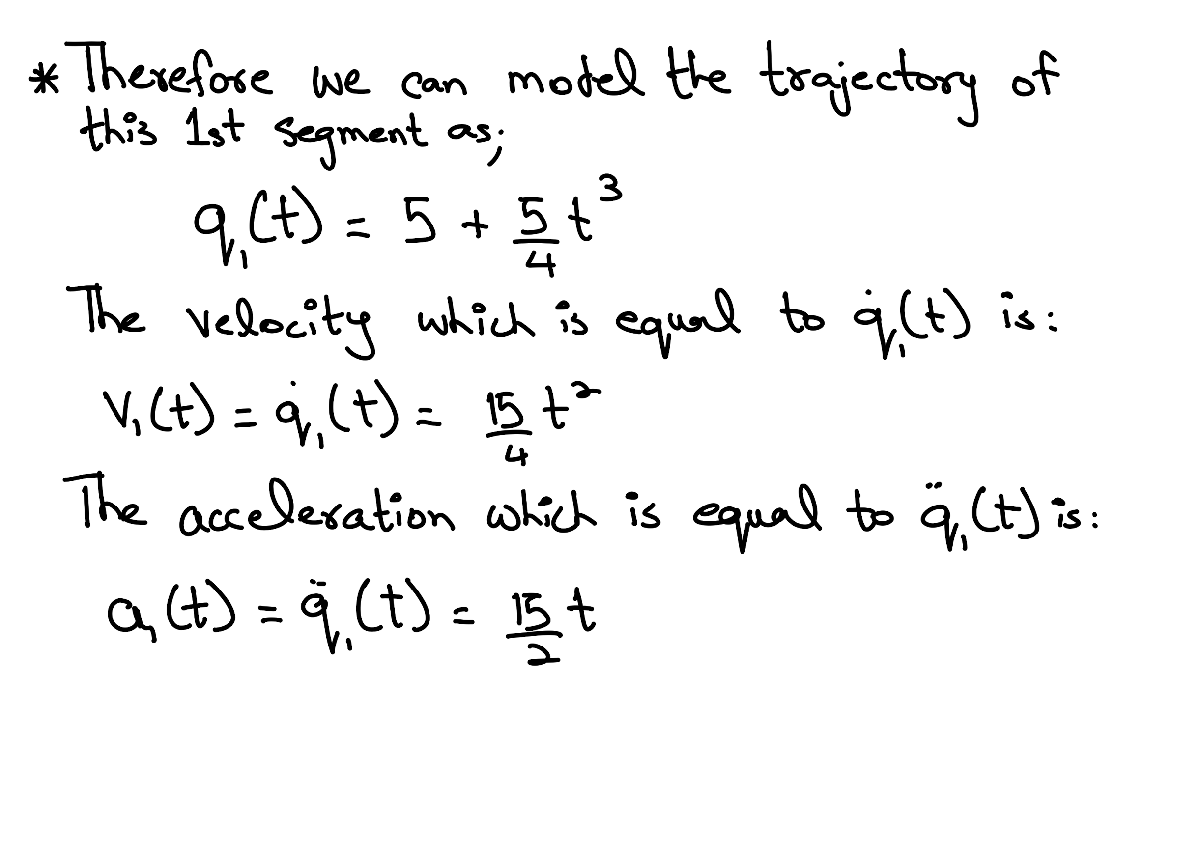

**Fourth Segment**

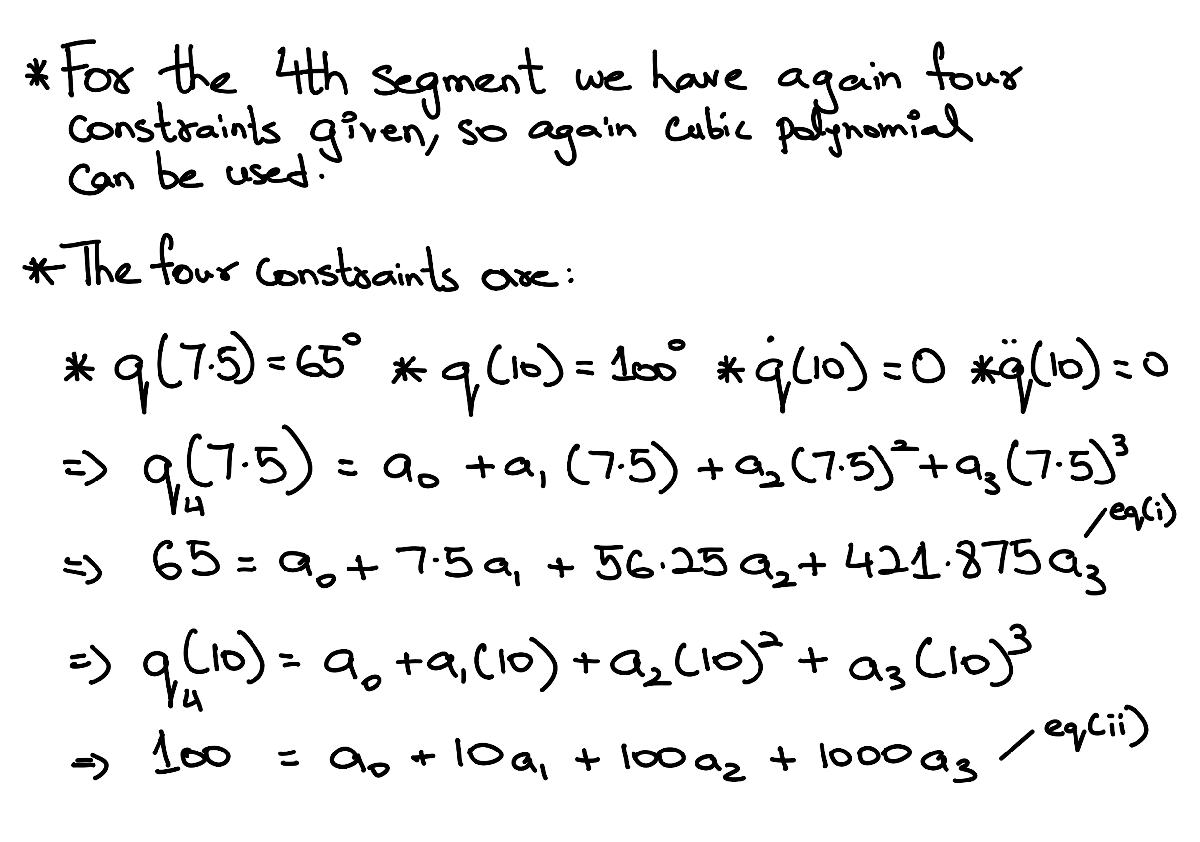

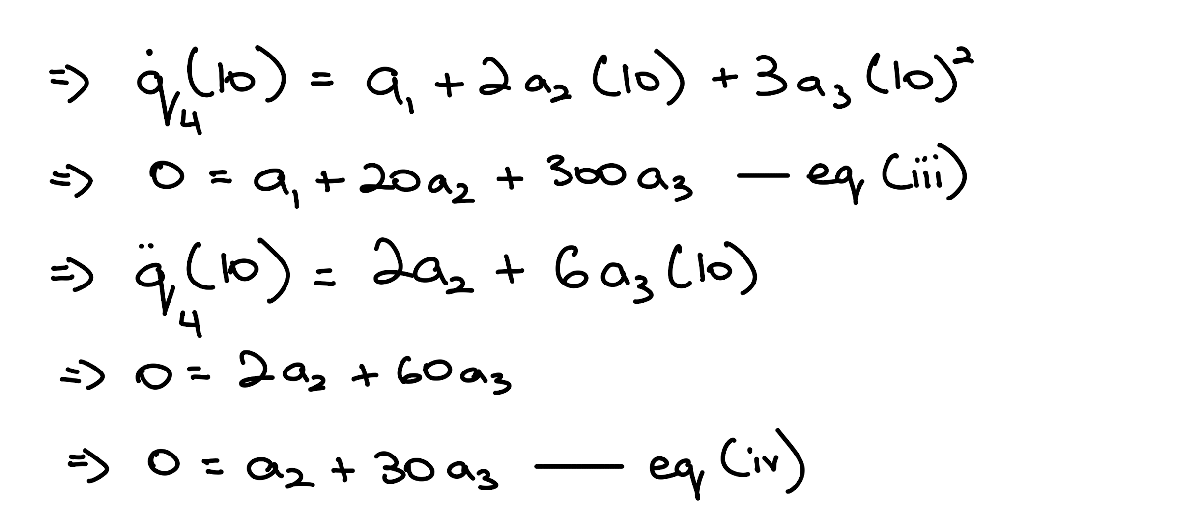

syms a0 a1 a2 a3 
coeff4 = solve({a0 + 7.5*a1 + 56.25*a2 + 421.875*a3 == 65, ...
                a0 + 10*a1 + 100*a2 + 1000*a3 == 100, ...
                a1 + 20*a2 + 300*a3 == 0, ...
                a2 + 30*a3 == 0}, ...
                [a0,a1,a2,a3])

coeff4 = struct with fields:
    a0: -2140
    a1: 672
    a2: -336/5
    a3: 56/25


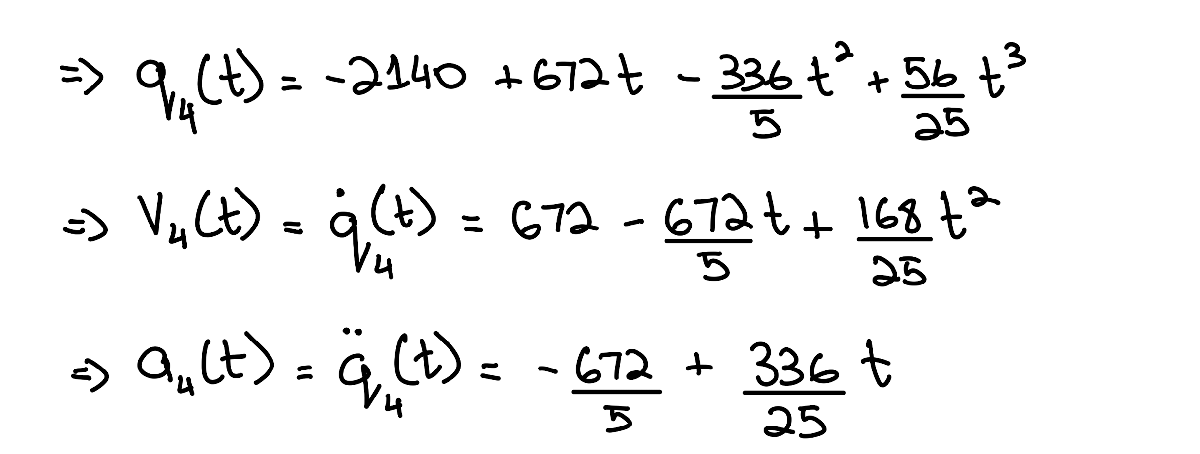

**Second Segment**

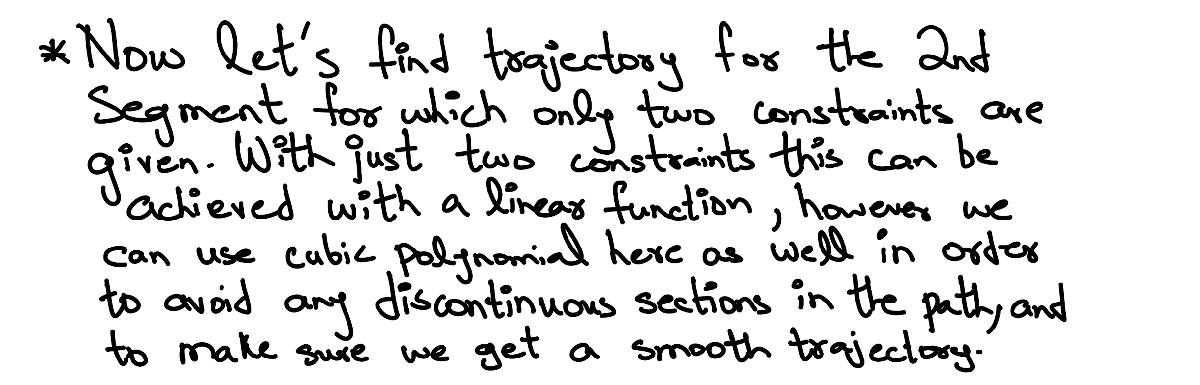

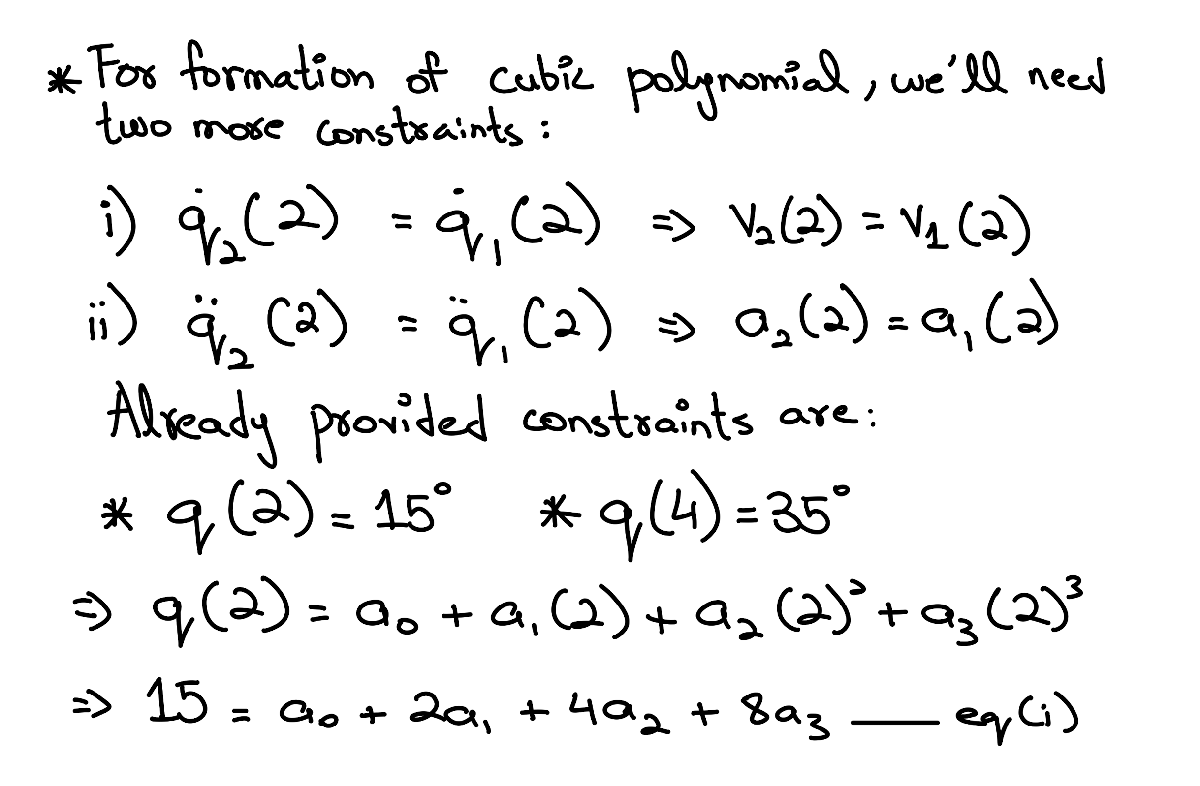

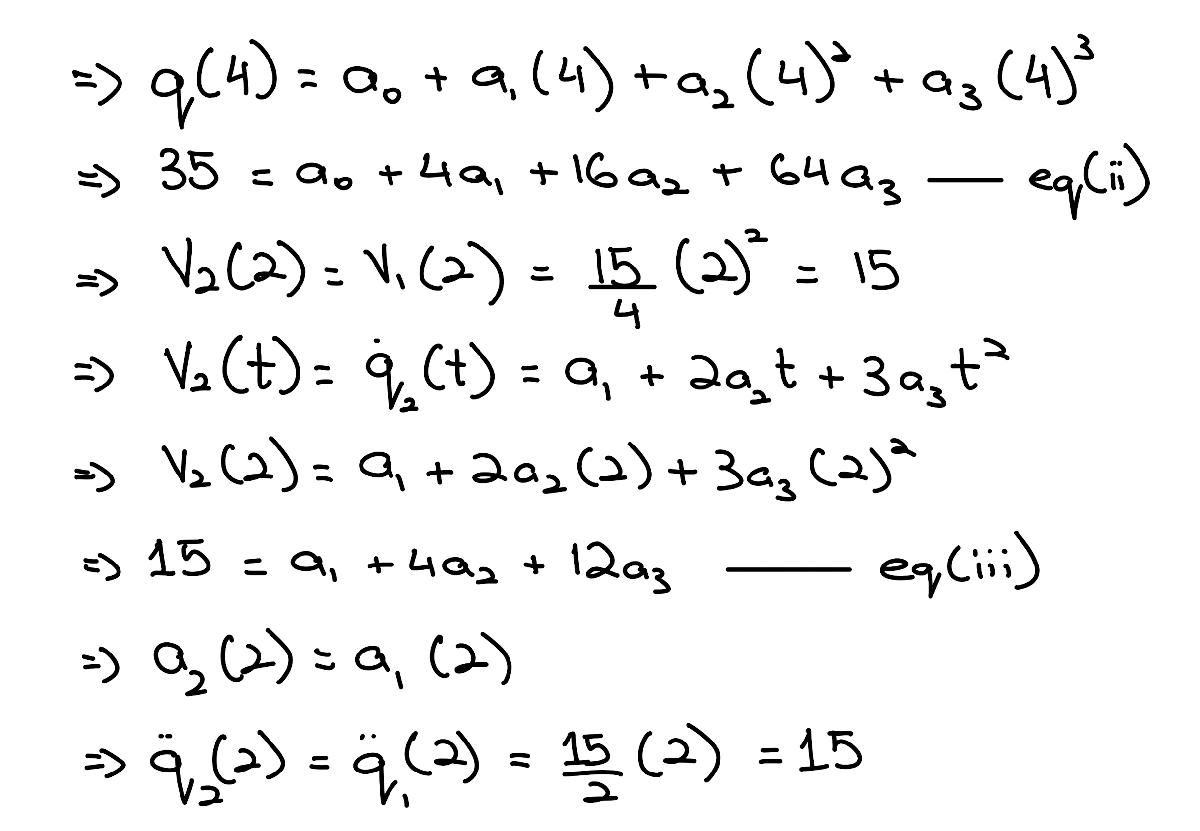

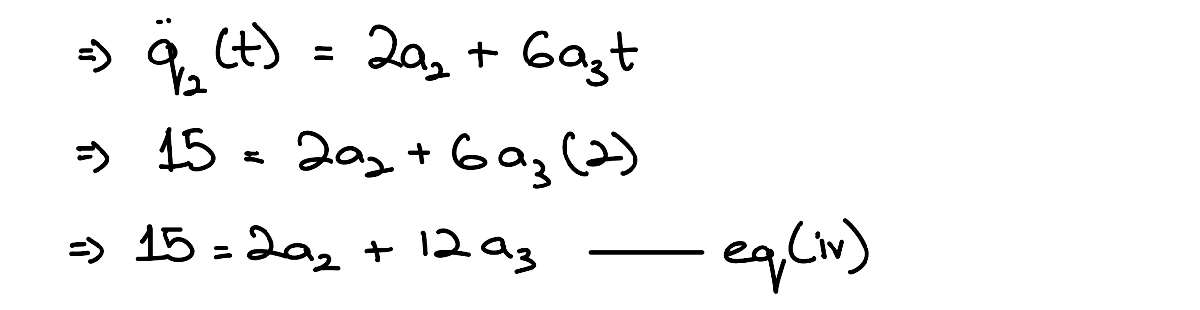

syms a0 a1 a2 a3
coeff2 = solve({a0 + 2*a1 + 4*a2 + 8*a3 == 15, ...
                a0 + 4*a1 + 16*a2 + 64*a3 == 35, ...
                a1 + 4*a2 + 12*a3 == 15, ...
                2*a2 + 12*a3 == 15}, ...
                [a0,a1,a2,a3])

coeff2 = struct with fields:
    a0: 55
    a1: -75
    a2: 75/2
    a3: -5


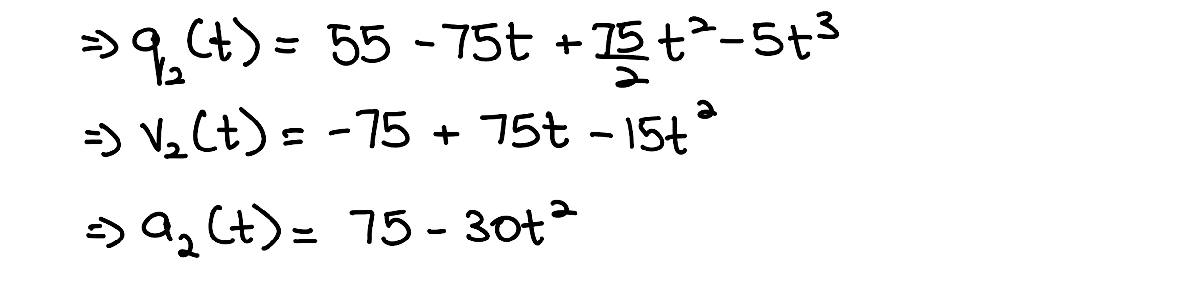

**Third Segment**

syms a0 a1 a2 a3
coeff3 = solve({a0 + 4*a1 + 16*a2 + 64*a3 == 35, ...
                a0 + 7.5*a1 + 56.25*a2 + 421.875*a3 == 65, ...
                a1 + 8*a2 + 48*a3 == -15, ...
                2*a2 + 24*a3 == -405}, ...
                [a0,a1,a2,a3])

coeff3 = struct with fields:
    a0: -2391055/343
    a1: 1534755/343
    a2: -631035/686
    a3: 20505/343


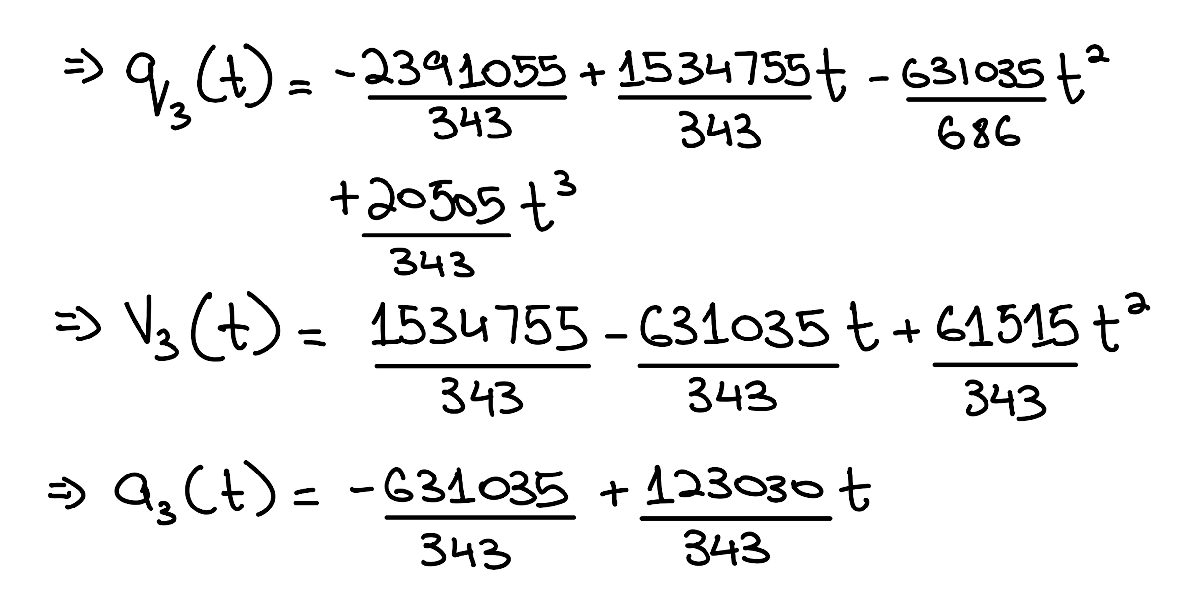

**Complete Trajectory**

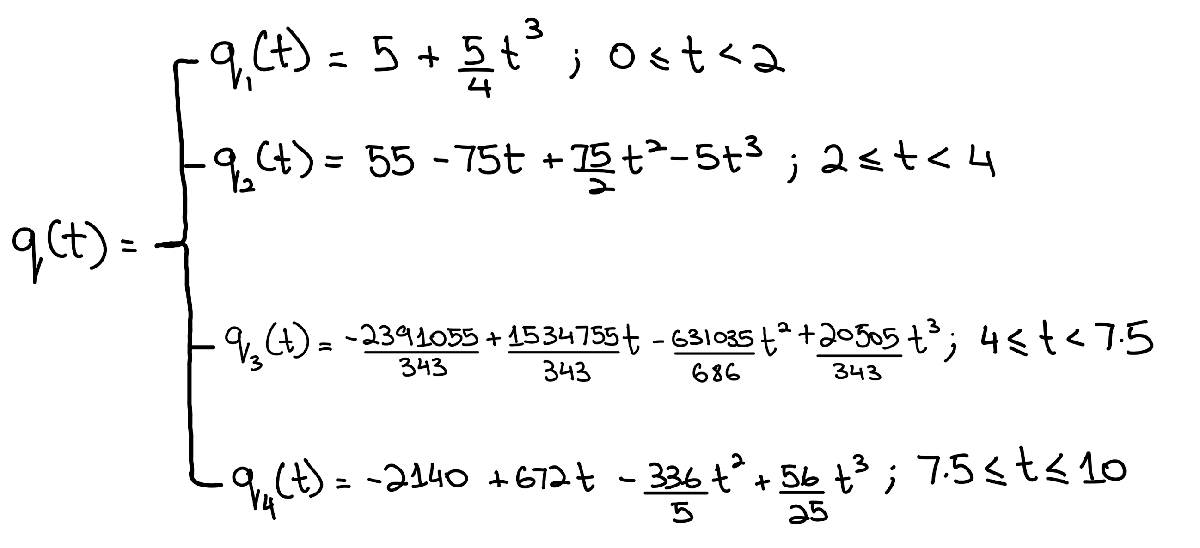

## **Problem # 2**

## **Part - a**

The route consists of two semicircular segments. The initial segment extends from point P1 = (1.5, 0.5) to the y-axis at (0, 0.5). This relationship can be represented as:


$$X_1(s) = 0.75\cos s + 0.75 \\
Y_1(s) = 0.75\sin s + 0.5$$


where $s\in \left\lbrack 0,-\pi \right\rbrack$.

Similarly, the second segment of the path is:


$$X_2(s) = 0.75\cos (s) - 0.75 \\
Y_2(s) = 0.75\sin (s) + 0.5,$$


where $s\in \left\lbrack 0,\pi \right\rbrack$.

### Plotting the Path for verification:

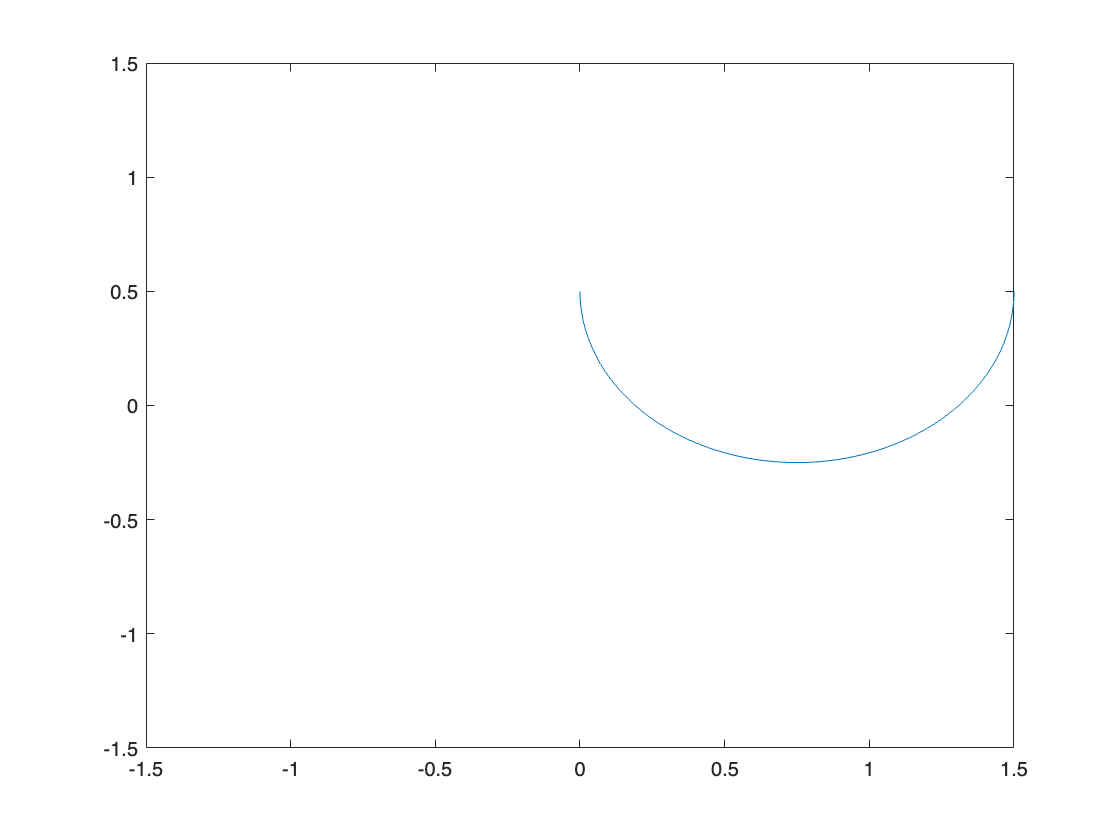

syms s X1 Y1 X2 Y2 X(t) Y(t)
s = linspace(0, -pi);
X1 = 0.75*cos(s)+0.75;
Y1 = 0.75*sin(s)+0.5;
plot(X1,Y1); xlim([-1.5 1.5]); ylim([-1.5 1.5]);

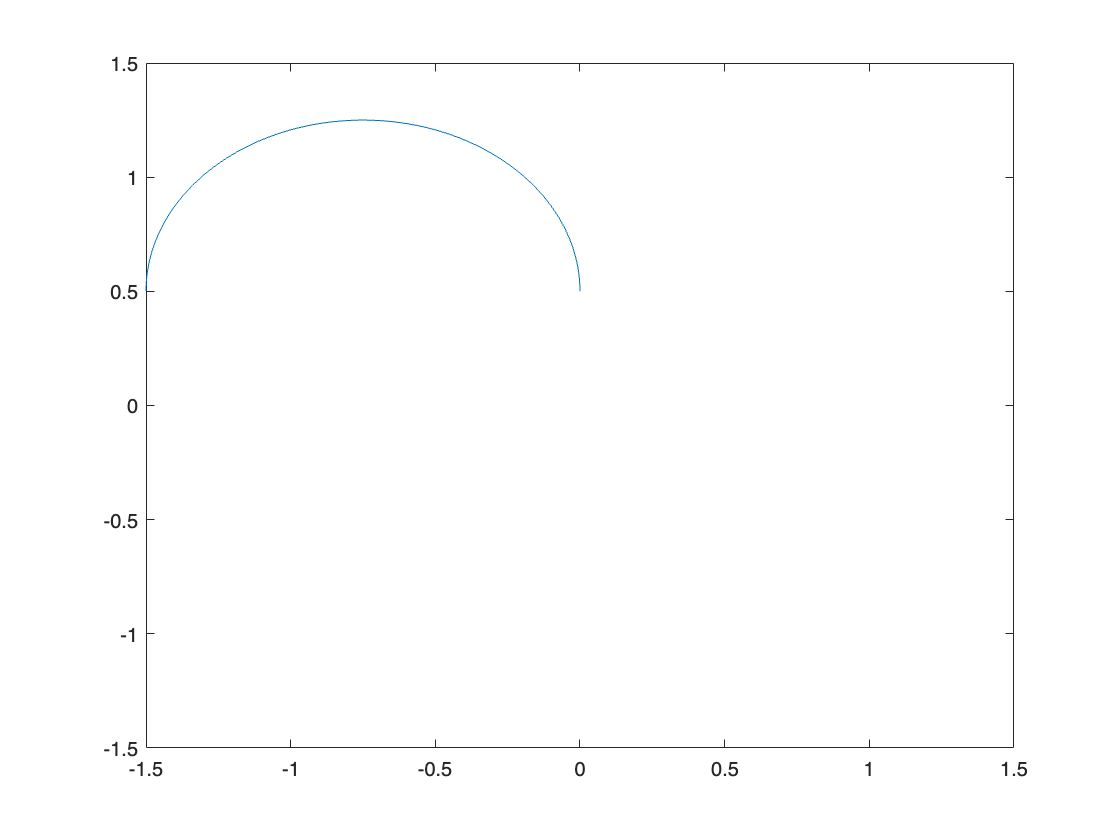

s = linspace(0,pi);
X2 = 0.75*cos(s)-0.75;
Y2 = 0.75*sin(s)+0.5;
plot(X2,Y2);xlim([-1.5 1.5]); ylim([-1.5 1.5]);

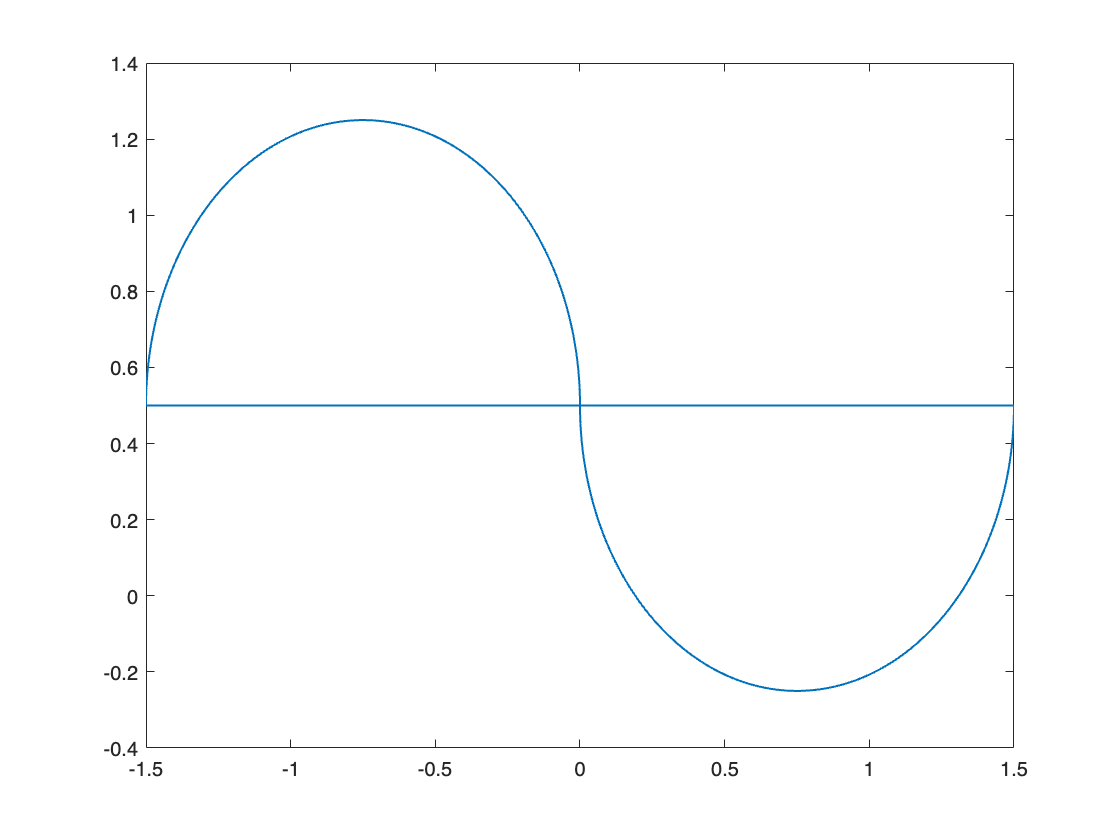

plot([X2 X1],[Y2 Y1], LineWidth=1);

### Establishing Trajectory

To establish a trajectory, we require *s*(*t*), which can be represented as two linear segments, which are identical:


$$s_1(t) = a_1t+a_0,$$


The first segment is defined for $t\in[0,T/2]$

Considering *T* as the total duration of the trajectory, and since both segments are identical with a constant velocity, each segment will take $\frac{T}{2}$ time. The second segment will follow the same formulation but will be defined for $t\in[T/2,T]$. 


$$s_2(t) = a_1t+a_0,$$


#### For First Segment

The constraints are $s_1(0) = 0$ and $s_1(T/2) = -\pi$.

syms a0 a1 T
coeff1 = solve({a1*(0) + a0 == 0, ...
                a1*(T/2) + a0 == -pi}, ...
                [a0, a1])

coeff1 = struct with fields:
    a0: 0
    a1: -(2*pi)/T


Therefore,


$$s_1(t) = -\frac{2\pi}{T}t.$$


#### For Second Segment

The constraints are $s_2(T/2) = 0$ and $s_2(T) = \pi$.

syms a0 a1
coeff2 = solve({a1*(T/2) + a0 == 0, ...
                a1*(T) + a0 == pi}, ...
                [a0, a1])

coeff2 = struct with fields:
    a0: -pi
    a1: (2*pi)/T


Therefore,


$$s_2(t) = \frac{2\pi}{T}t - \pi.$$


#### Combining both Segments

Thus,


$$s\left(t\right)=\left\lbrace \begin{array}{ll}
-\frac{2\pi }{T}t, & t\in \left\lbrack 0,\frac{T}{2}\right\rbrack \\
\frac{2\pi }{T}t-\pi , & t\in \left\lbrack \frac{T}{2},T\right\rbrack 
\end{array}\right.$$


#### Determining T

The constancy of velocity throughout the motion allows for the determination of a constant time interval *T*.

Velocity = $V=\sqrt{\overset{\ldotp }{{X\left(s\left(t\right)\right)}^2 } +\overset{\ldotp }{{Y\left(s\left(t\right)\right)}^2 } }$= 1m/s

X(t) = $\left\lbrace \begin{array}{cl}
\frac{3\,\cos \left(-\frac{2\pi }{T}t\right)}{4}+\frac{3}{4} & \;\textrm{if}\;\;t\in \left\lbrack 0,\frac{T}{2}\right\rbrack \\
\frac{3\,\sin \left(\frac{2\pi }{T}t-\pi \right)}{4}-\frac{1}{2} & \;\textrm{if}\;\;s\in \left\lbrack \frac{T}{2},T\right\rbrack 
\end{array}\right.$

Y(t) = $\left\lbrace \begin{array}{cl}
\frac{3\,\sin \left(-\frac{2\pi }{T}t\right)}{4}+\frac{1}{2} & \;\textrm{if}\;\;s\in \left\lbrack 0,\frac{T}{2}\right\rbrack \\
\frac{3\,\sin \left(\frac{2\pi }{T}t-\pi \right)}{4}+\frac{1}{2} & \;\textrm{if}\;\;s\in \left\lbrack \frac{T}{2},T\right\rbrack 
\end{array}\right.$

Therefore, 


$$\dot{X}(t) = \left\lbrace \begin{array}{cl}
\frac{3\pi}{2T}\,\sin \left(-\frac{2\pi t}{T}\right) & \;\textrm{if}\;\;t\in \left\lbrack 0,T/2 \right\rbrack \\
\frac{3\pi}{2T}\,\cos \left(\frac{2\pi t}{T}-\pi\right) & \;\textrm{if}\;\;t\in \left\lbrack T/2 ,T \right\rbrack 
\end{array}\right.$$



$$\dot{Y}(t) = \left\lbrace \begin{array}{cl}
-\frac{3\pi}{2T}\,\cos \left(-\frac{2\pi t}{T}\right) & \;\textrm{if}\;\;t\in \left\lbrack 0,T/2 \right\rbrack \\
\frac{3\pi}{2T}\,\cos \left(\frac{2\pi t}{T}-\pi\right) & \;\textrm{if}\;\;t\in \left\lbrack T/2 ,T \right\rbrack 
\end{array}\right.$$


Now,

V = $\sqrt{{\left(\frac{3\pi }{2T}\sin \left(-\frac{2\pi t}{T}\right)\right)}^2 +{\left(-\frac{3\pi }{2T}\cos \left(-\frac{2\pi t}{T}\right)\right)}^2 }$ = $\frac{3\pi }{2T}$

V = 1

1 = $\frac{3\pi }{2T}$

T = $\frac{3\pi }{2}$

#### Final Trajectory

The final trajectory is:


$$X(t) = \left\lbrace \begin{array}{cl}
\frac{3}{4}\left[1+\cos \left(-\frac{2 t}{3}\right)\right] & \;\textrm{if}\;\;t\in \left\lbrack 0,3\pi/4 \right\rbrack \\
\frac{1}{2}+\frac{3}{4}\sin \left(\frac{2 t}{3}-\pi\right) & \;\textrm{if}\;\;t\in \left\lbrack 3\pi/4 ,3\pi/2 \right\rbrack 
\end{array}\right.$$


$Y(t) = \frac{1}{2}+\frac{3}{4}\sin\left(-\frac{2 t}{3}\right), \quad t\in[0,3\pi/2]$.

## **Part - b**

The trajectory time T has already been determined in part (a). T=$\frac{3\pi }{2}$.

## **Part - c**

We know closed-form solution for IK of this manipulator from the slides. The elbow-down solution is


$$\theta_1(t) = \arctan2(Y(t),X(t))-\arccos \left(\frac{l_1^2+X^2+Y^2-l_2^2}{2l_1\sqrt{X^2+Y^2}}\right) \\
\theta_2(t) = \pi-\arccos \left(\frac{l_1^2+l_2^2-X^2-Y^2}{2l_1l_2}\right).$$


The elbow-up solution is:


$$\theta_1(t) = \arctan2(Y(t),X(t))+\arccos \left(\frac{l_1^2+X^2+Y^2-l_2^2}{2l_1\sqrt{X^2+Y^2}}\right) \\
\theta_2(t) = -\pi+\arccos \left(\frac{l_1^2+l_2^2-X^2-Y^2}{2l_1l_2}\right).$$


Let's use the elbow-down solution here.

We are given that $l_1 =l_2 =1m$. 

Substituting $X(t), Y(t)$ from the previous part in this expression:

syms t Q1(t) Q2(t)

l1 = 1; l2 = 1;
X(t) = piecewise (0 <= t < 3*pi/4, 0.75*cos(-2*t/3)+0.75 , 3*pi/4 <= t <= 3*pi/2, 0.75*sin(2*t/3 - pi)+0.5);
Y(t) = 0.75*sin(-2*t/3)+0.5;
Q1(t) = simplify(atan2(Y(t),X(t)) - acos((l1^2+X(t)^2+Y(t)^2-l2^2)/(2*l1*sqrt(X(t)^2+Y(t)^2))))

$$Q1(t) = \begin{array}{l} \left\{ \begin{array}{cl} -\mathrm{acos}\left(\frac{\sqrt{\sigma_{2}+9\,{\sigma_{1}}^{2}}}{8}\right)-\mathrm{atan}\left(\frac{3\,\sigma_{3}-2}{3\,\sigma_{1}}\right) & \text{ if }t\in \left[0,\frac{3\,\pi }{4}\right)\\ -\mathrm{acos}\left(\frac{\sqrt{2}\,\sigma_{2}}{8\,\left|3\,\sigma_{3}-2\right|}\right)+\text{angle}\left(\frac{1}{2}+\sigma_{3}\,\left(-\frac{3}{4}-\frac{3}{4}\,\mathrm{i}\right)+\frac{1}{2}\,\mathrm{i}\right) & \text{ if }t\in \left[\frac{3\,\pi }{4},\frac{3\,\pi }{2}\right] \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{2\,t}{3}\right)+1\\ \sigma_{2}={\left(3\,\sigma_{3}-2\right)}^{2}\\ \sigma_{3}=\sin\left(\frac{2\,t}{3}\right) \end{array}$$

Q2(t) = simplify(pi-acos((l1^2+l2^2-X(t)^2-Y(t)^2)/(2*l1*l2)))

$$Q2(t) = \begin{array}{l} \left\{ \begin{array}{cl} \pi -\mathrm{acos}\left(\frac{\sigma_{1}}{8}-\frac{9\,\cos\left(\frac{2\,t}{3}\right)}{16}+\frac{5}{16}\right) & \text{ if }t\in \left[0,\frac{3\,\pi }{4}\right)\\ \pi -\mathrm{acos}\left(1-{\left(\frac{\sigma_{1}}{4}-\frac{1}{2}\right)}^{2}\right) & \text{ if }t\in \left[\frac{3\,\pi }{4},\frac{3\,\pi }{2}\right] \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=3\,\sin\left(\frac{2\,t}{3}\right) \end{array}$$

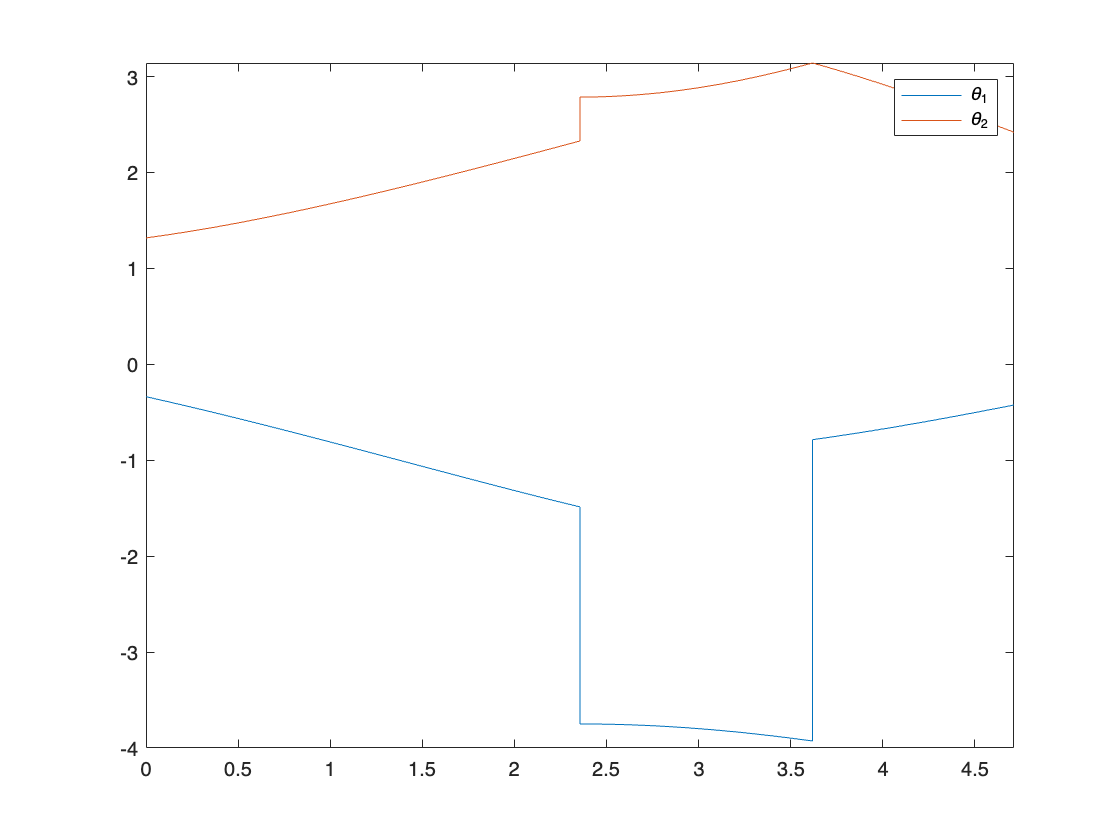

figure;
fplot(Q1(t), [0,3*pi/2])
hold on
fplot(Q2(t), [0,3*pi/2])
legend("\theta_1","\theta_2");

## **Part - d**

To find the angular velocities we can simply differentiate both theta 1 and theta 2. 					

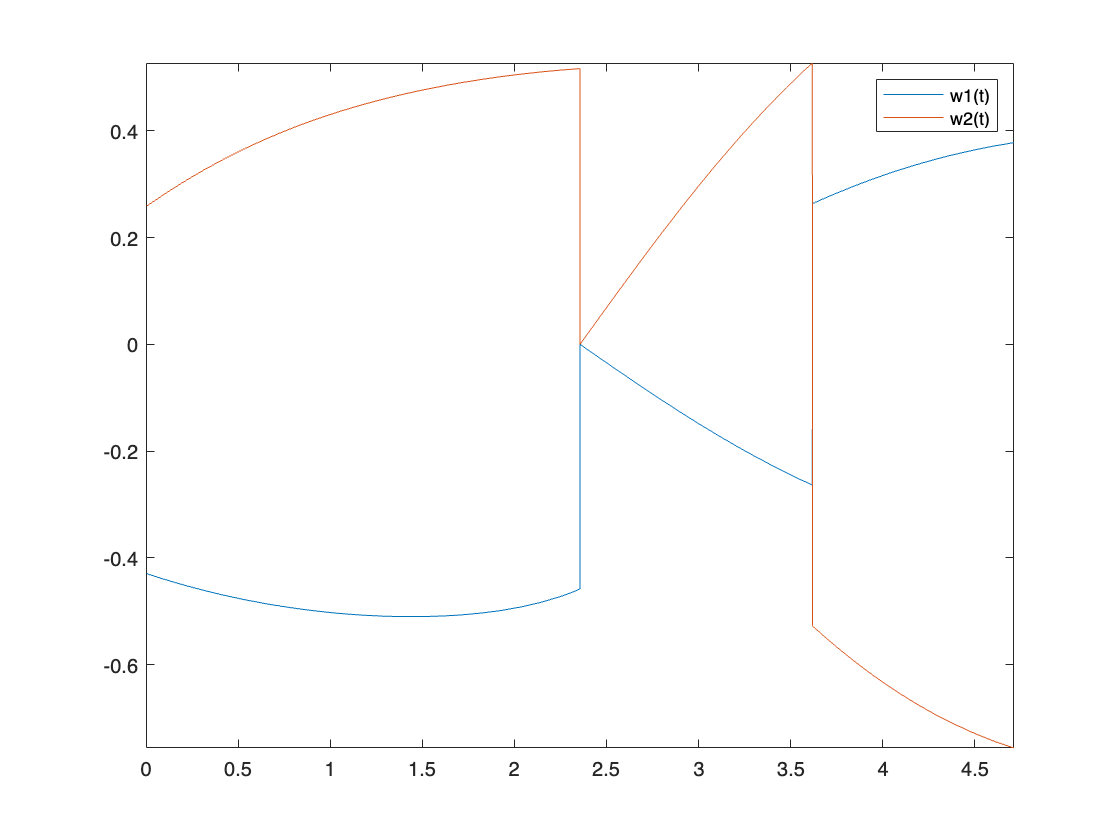

syms w1(t) w2(t)
clf;
figure;
w1(t)= simplify(diff(Q1(t),t));
fplot(w1(t),[0,3*pi/2]);
hold on;
w2(t)= simplify(diff(Q2(t),t));
fplot(w2(t),[0,3*pi/2]);
legend("w1(t)","w2(t)")

This plot shows us the magnitude of the angular velocities at different values of t.

## **Part - e**

To find the accelerations we can simply differentiate both w1 and w2. 	

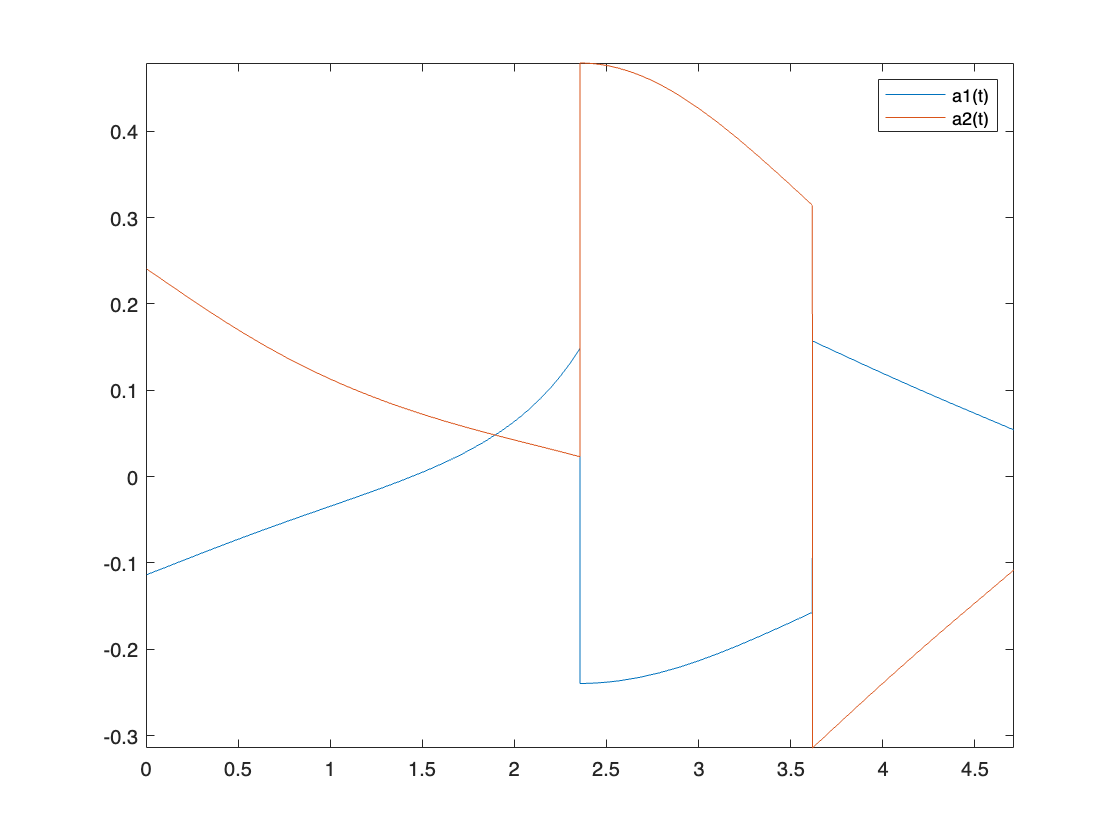

syms a1(t) a2(t)
clf;
figure;
a1(t)= simplify(diff(w1,t));
fplot(a1(t),[0,3*pi/2]);
hold on;
a2(t)= simplify(diff(w2,t));
fplot(a2(t),[0,3*pi/2]);
legend("a1(t)","a2(t)")

This plot shows us the magnitude of the accelerations at different values of t.

## **Problem # 3**

## **Part - a**

The typical model of a manipulator outlined in the slides is:

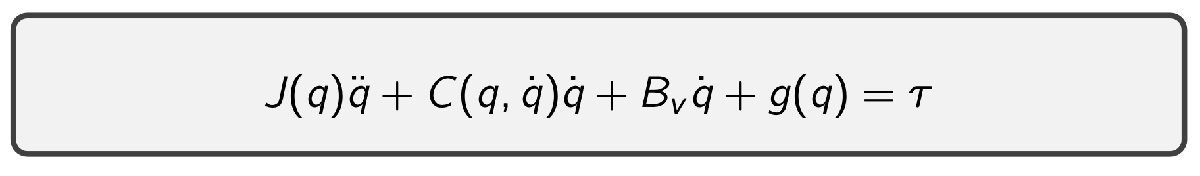

The mass matrix, Coriolis matrix, and gravitational terms for the 2R manipulator are as follows:

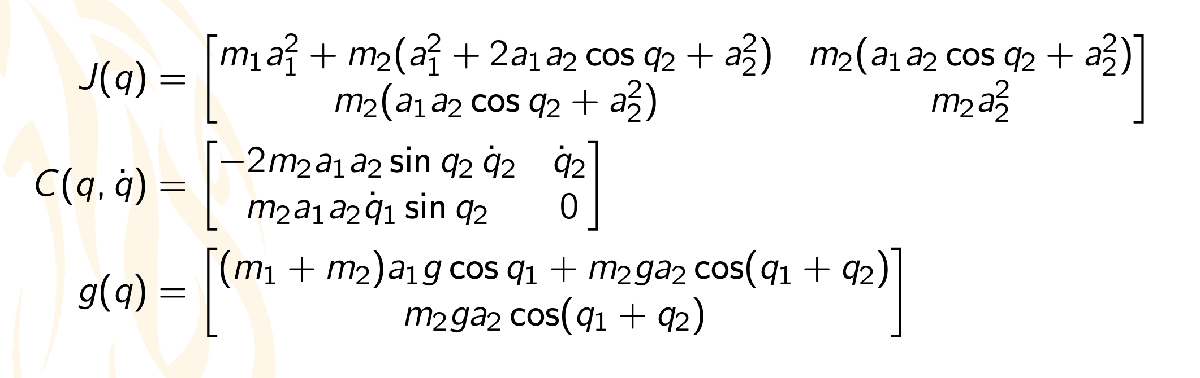

Numerically creating these matrices using the given parameter values. We'll omit the friction values since they're not specified.

Here in the above formula a1 and a2 specify the link lengths, which in our case our modeled by l1 and l2 and both are equal to 1m.

m1=1;
m2=1;
l1=1;
l2=1;
g=9.8;
J(t) = [m1*l1^2+m2*(l1^2+2*l1*l2*cos(Q2(t))+l2^2), m2*(l1*l2*cos(Q2(t))+l2^2);
    m2*(l1*l2*cos(Q2(t))+l2^2), m2*l2^2];
C(t) = [-2*m2*l1*l2*sin(Q2(t))*w2(t), w2(t);
    m2*l1*l2*sin(Q2(t))*w1(t),  0];
G(t) = [(m1+m2)*l1*g*cos(Q1(t))+m2*g*l2*cos(Q1(t)+Q2(t));
    m2*g*l2*cos(Q1(t)+Q2(t))];

So the required torque by each joint to execute our desired trajectory, as a function of time, is computed below:

tau(t) = simplify(J(t)*[a1(t);a2(t)]+C(t)*[w1(t);w2(t)]+G(t))

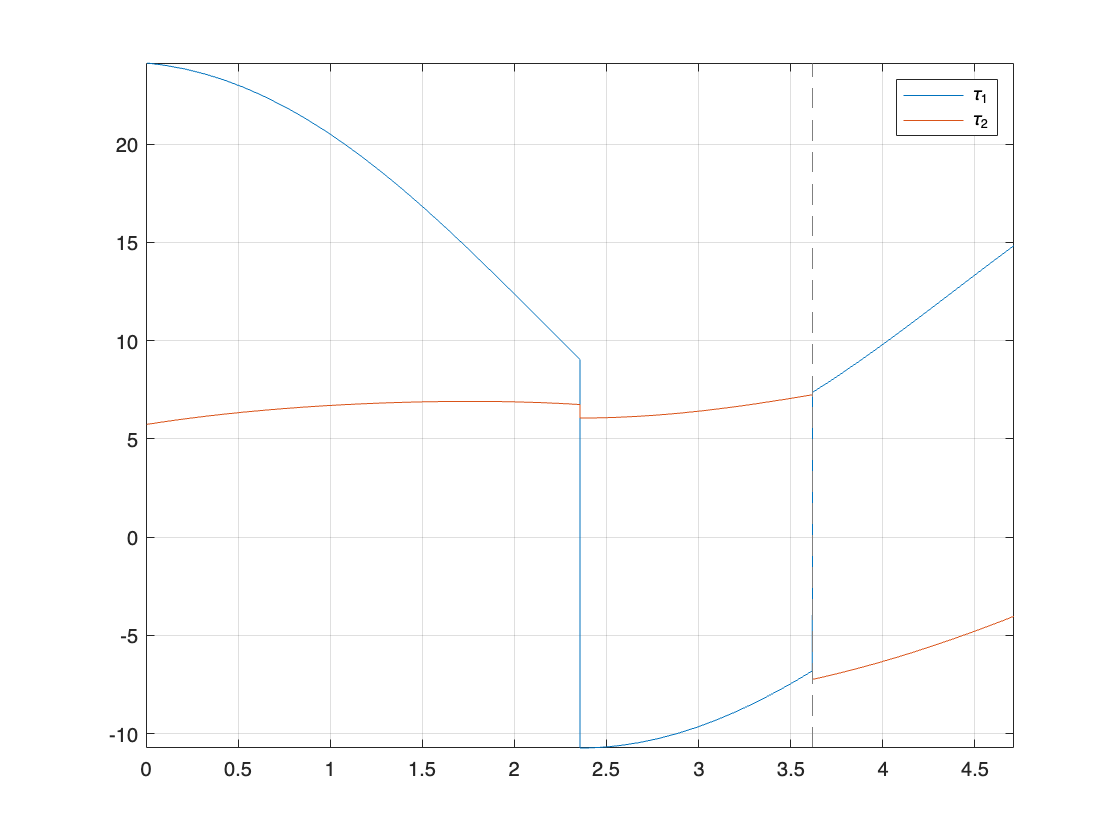

torque = tau(t);
clear h;
figure;
h(1) = fplot(torque(1),[0,3*pi/2]);
hold on;
h(2) = fplot(torque(2),[0,3*pi/2]);
grid on;
hl = legend(h,"\tau_1","\tau_2");

## **Part - d**

For the computed torque controller, we will define our control variable, torque as follows:


$$\tau = C(q,\dot{q})\,\dot{q}+g(q) + J(q)\,(\ddot{q}_d+\text{Feedback Controller)$$


The mass given initially was 1kg, however part c of this question suggested to increase mass by 10%, we will set it at this and we'll see if the controller is able to compensate for that.

m1 = 1.1;
m2 = 1.1;
l1 = 1;
l2 = 1;
g = 9.8;

% Define ODE function 
dqdt = @(ti,q) ([q(3); ...
                 q(4); ...
                 2*m2*l1*l2*sin(q(2))*q(4)*q(3)-q(4)^2-(m1+m2)*l1*g*cos(q(1))-m2*g*l2*cos(q(1)+q(2)); ...
                 -m2*l1*l2*sin(q(2))*q(3)^2-m2*g*l2*cos(q(1)+q(2))]+[0;0;controller(ti,q,Q1, Q2, a1, a2)]);

% Define the mass matrix
M = @(ti,q)[1 0 0 0; 
            0 1 0 0; 
            0 0 m1*l1^2+m2*(l1^2+2*l1*l2*cos(q(2))+l2^2) m2*(l1*l2*cos(q(2))+l2^2);
            0 0 m2*(l1*l2*cos(q(2))+l2^2) m2*l2^2];

% Set the mass-matrix option of ode
options = odeset('Mass',M);
% Solve the ODE
[ti,q] = ode45(dqdt, tspan, q0,options)

ti =     0.0000
    0.0064
    0.0128
    0.0192
    0.0256
    0.0320
    0.0384
    0.0448
    0.0512
    0.0563


q =    -0.3373    1.3181   -0.8582    0.5164
   -0.3428    1.3214   -0.8565    0.5089
   -0.3483    1.3246   -0.8466    0.4859
   -0.3536    1.3276   -0.8286    0.4479
   -0.3588    1.3303   -0.8034    0.3968
   -0.3639    1.3326   -0.7720    0.3353
   -0.3687    1.3346   -0.7358    0.2663
   -0.3733    1.3360   -0.6961    0.1930
   -0.3776    1.3370   -0.6544    0.1191
   -0.3809    1.3375   -0.6206    0.0618


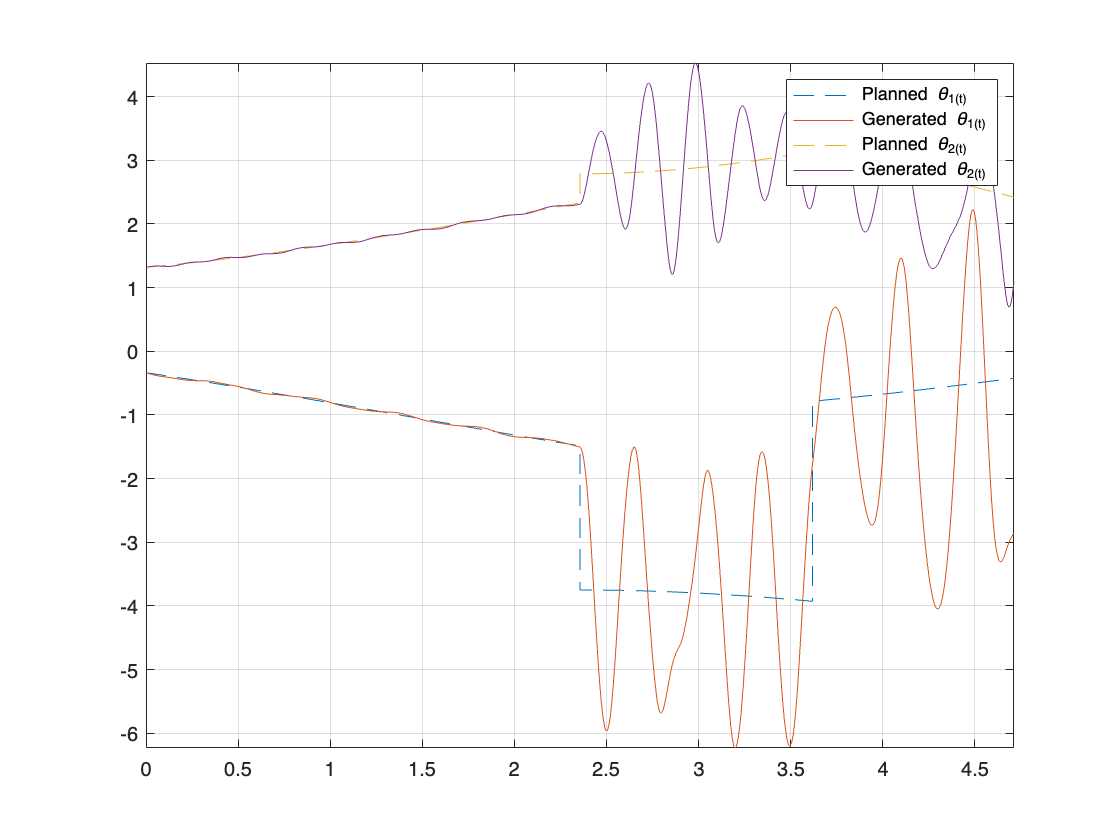

figure;
clear h;
h(1) = fplot(Q1,[0,3*pi/2],'--');
hold on;
h(2) = plot(ti,q(:,1));
h(3) = fplot(Q2,[0,3*pi/2],'--');
h(4) = plot(ti,q(:,2));
grid on;
legend(h,'Planned \theta_1(t)','Generated \theta_1(t)','Planned \theta_2(t)', 'Generated \theta_2(t)');

## Problem # 4

## Part - a

**Asghar:** I spent 12 hours on this homework, with 5 hours being together with Huzaifah solving the questions together on an online Discord call. 

**Huzaifah**: I spent 16 hours on this homework, with 5 hours being together with Asghar solving the given questions together on an online Discord call.

## Part - b

**Asghar: **My advice hasn’t really changed from my previous feedback, however, I would strongly recommend students to also study from the book to build up their fundamentals. There is this underlying fear that makes you hesitate when picking up the book especially for a course like this, aka Robotics which is very maths heavy as well as logic heavy. Ironically in my experience, it is of no use trying to find shortcut through the internet or by trying to force you to understand the slides that you just can’t. It’s better to give up and just open the book. It will take time but the way it starts from zero (obviously assuming a basic foundation beforehand), it makes life alot easier. So yeah open the book even if it sounds like an advice that is not revolutionary by any means. Your stubbornness will cost you far more emotional and mental energy than you need to.

**Huzaifah**: Not a big advice, but I would recommend students to always start their homework early cause they can ask the professor for the concepts they are weak at immediately. The thing is, this homework being given to us just before the final exams, made it far more hectic than it needed to be. It was very hard to find time for it, so when we got around actually working on the homework, it was way too last minute resulting in too much panic, that wavered our concentration as well as wasted alot more time than we should have. It is important to balance your time, have strong fundamentals when starting the homework to ensure the least amount of time is wasted. It also saves you from needless anxiety. 

## Part - c

## i)

**Asghar: **

These problems have really immersed me in the world of trajectory planning and control strategies for robotic systems. Problem 1 was all about honing our skills in crafting trajectories that adhere strictly to speed and acceleration limits, laying down the foundational knowledge. Moving on to Problem 2, we delved deeper into Cartesian space, where we crafted a controller guiding our 2R manipulator through an intricate trajectory. Then, in Problem 3, we were challenged to apply all our expertise to design a controller manoeuvring our 2R manipulator through real-world obstacles. Overall, these exercises taught me crucial skills that are pivotal in robotics. By grappling with trajectory generation under velocity and acceleration constraints, I've gained a deeper understanding of ensuring smooth, precise movements. 

Additionally, exploring Cartesian trajectory planning has revealed the delicate interplay between position and velocity control, essential for accurate robotic arm movements. Lastly, designing controllers for manipulators has highlighted the significance of robustness and adaptability in handling uncertainties inherent in robotics applications. Moreover, as we delve into other outcomes, such as generating trajectories with velocity and acceleration constraints, understanding the mathematical model of geared DC motors, and devising control strategies for second-order dynamical systems, I'm eager to deepen my knowledge and expertise in these crucial areas of robotics.

**Huzaifah: **

These learning objectives in robotics cover crucial areas for efficient and effective robot operation. Firstly, mastering trajectory planning with velocity and acceleration constraints ensures smooth and safe robot movement, reducing risks of instability and mechanical strain. Secondly, understanding and utilizing mathematical models of geared DC motors allows for precise analysis and control of motor behavior, enhancing overall system performance. Lastly, designing control strategies for second-order dynamical systems enables the development of responsive and stable control algorithms tailored to specific robotic applications, ensuring optimal performance in various tasks. Overall, these objectives underscore the importance of proficiency in trajectory planning, motor modeling, and control design for achieving robust and efficient robot behavior.

## ii)

**Asghar:**

Achieving each of the learning outcomes related to trajectory planning is crucial for understanding and building robots effectively for several reasons. Firstly, understanding trajectory generation with constraints is essential because it enables robots to move smoothly and efficiently while respecting physical limitations, ensuring safe operation in real-world environments. 

Without this understanding, robots may exhibit jerky or unsafe movements, hindering their practical utility. Secondly, mastering Cartesian trajectory planning is vital for robots that operate in three-dimensional spaces, such as robotic arms used in manufacturing or medical robotics. This skill allows engineers to specify precise end-effector movements, enhancing the robot's ability to perform complex tasks with accuracy. 

Thirdly, applying trajectory planning and control strategies is necessary for designing controllers that can accurately track desired trajectories in the presence of disturbances or uncertainties. This capability is crucial for achieving reliable performance in various robotic applications, from automated assembly lines to robotic surgery systems. Finally, understanding computed torque control and robustness is important for ensuring that robotic systems can maintain stability and performance even in challenging conditions or when facing unpredictable disturbances. Overall, mastery of these trajectory planning concepts is fundamental for building robots that can operate effectively, safely, and reliably in diverse real-world scenarios.

**Huzaifah:**

Homework 5 outlines a comprehensive exploration of trajectory planning in robotics, covering various scenarios and techniques vital for understanding motion control in robotic systems. The learning outcomes encapsulated in this assignment span trajectory generation with constraints, Cartesian trajectory planning, applying trajectory planning and control strategies, and computed torque control with a focus on robustness. 

Each problem presents real-world use cases, such as generating smooth trajectories while adhering to velocity and acceleration constraints, designing controllers for manipulators to track desired trajectories accurately, and simulating systems to observe the effects of parameter inaccuracies on performance. 

Trajectory planning plays a pivotal role in a broader spectrum of robotics applications, ranging from industrial automation to autonomous vehicles and medical robotics. It enables robots to navigate complex environments efficiently, execute precise movements in manufacturing processes, and perform delicate surgical procedures with accuracy and safety. Mastery of trajectory planning concepts is essential for engineers and researchers working in diverse fields of robotics, facilitating advancements in automation, mobility, and human-robot interaction. 

## iii)

**Asghar:**

Trajectory planning with velocity and acceleration constraints seems crucial for ensuring smooth and safe robot movement. However, I wonder about the nuances of implementing such constraints in dynamic environments where obstacles and uncertainties are prevalent. Additionally, delving into the intricacies of mathematical modeling for geared DC motors peakes my curiosity. I'd like to explore how factors like temperature variations or wear and tear affect the accuracy of these models over time. As for control strategies, I’d like to understand what strategies are there to adapt to unpredictable environmental changes in terms of obstacles or conditions in real-time, and what are the trade-offs between stability and response time in dynamic scenarios? Are there innovative ways to integrate machine learning techniques to enhance the adaptability and robustness of control algorithms?

**Huzaifah:**

Trajectory planning is the art of mapping out a robot's movement over time, factoring in its position, velocity, and acceleration to ensure smooth and efficient motion. This skill is vital across various robotics tasks, such as pick-and-place operations, manipulation, industrial automation, and autonomous vehicles. However, challenges arise, like accurately defining coordinate frames and handling real-world uncertainties. Through studying trajectory planning, I learned skills like generating constrained trajectories, planning in Cartesian space, designing control strategies, and implementing computed torque control. Still, lingering questions remain about specific algorithms, diverse robot implementations, optimization techniques, and advanced control strategies. Delving deeper into these aspects promises a richer understanding of trajectory planning's role in robotics.

These are the following questions that popped in my mind as I was working on my assignment. What challenges arise when planning trajectories for multiple robots collaborating in a shared workspace,and how can these challenges be addressed? Can machine learning algorithms be used to learn effective trajectory planning strategies from data or experience? How can trajectory planning be designed to ensure safety and smooth interaction when robots work alongside humans?  How can sampling-based approaches like Rapidly-exploring Random Trees (RRTs, which we didn’t look into) be used for trajectory planning in complex environments?

## iv)

**Asghar: ** I feel I'm on the right track with trajectory planning, understanding the core concepts and the importance for real-world robots. I have answered most of this in part b), cause I would recommend students the same things that I did mistake on, and wanted to improve upon.

I need to get practical experience in the lab, and need to be comfortable with reading the book itself alot. 

**Huzaifah**: I too feel like I am mostly on right track, the only major thing that went wrong is the time management aspect. I would recommend students to always start their homework early and quickly solidify their foundations.  Not to mention, as we were lacking alot behind in lab work, most of the time that we left for robotics, went inside the lab work instead. So I would say that overall this course is painful, but in pain the real learning happens which elevates your thinking. So don't run away from difficult things, no matter how painful they seem at the moment.

function tau_computed = controller(t,q,theta_1, theta_2, a1, a2)
    m1 = 1;
    m2 = 1;
    l1 = 1;
    l2 = 1;
    g=9.8;
    persistent eint;
    persistent tprev;
    if isempty(eint)
        eint = [0;0];
        tprev = 0;
    end
    
    % This is compensating the corriolis and gravity terms
    tau_computed = [-2*m2*l1*l2*sin(q(2))*q(4)*q(3)+q(4)^2+(m1+m2)*l1*g*cos(q(1))+m2*g*l2*cos(q(1)+q(2));
                    m2*l1*l2*sin(q(2))*q(3)^2+m2*g*l2*cos(q(1)+q(2))];
    % Add the feedforward controller
    tau_computed = tau_computed + [m1*l1^2+m2*(l1^2+2*l1*l2*cos(q(2))+l2^2)*double(a1(t))+m2*(l1*l2*cos(q(2))+l2^2)*double(a2(t));  
                                   m2*(l1*l2*cos(q(2))+l2^2)*double(a1(t))+ m2*l2^2*double(a2(t))];
    % Add the feedback controller part
    Kp = 600;
    Ki = 100;
    e = [double(theta_1(t))-q(1); double(theta_2(t))-q(2)];
    dt = t-tprev;
    eint = eint + e*dt;
    tau_computed  = tau_computed + Kp*e + Ki*eint;
    tprev = t;
end